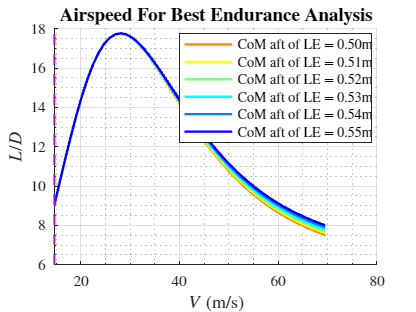

clc
clear

%% Conversions
feet_to_meters = 0.3048;
knots_to_ms = 0.515;

%% Aircraft Parameters
altitude = 339 * feet_to_meters; % [m]
mass = 23.5; % [kg]
flight_path_angle = deg2rad(0); % [rad]
gravity = 9.81; % [m/s2]

%% CG Positions
start = 0.5;  
stop = 0.55;   
step = 0.01;    
cg_position = (start:step:stop)';

%% Air Density
gas_constant = 287.05; % [Nm/KgK]
lapse_rate = -0.0065; % [K/m]
temperature = 288.16 + lapse_rate * altitude; % [K]
air_density = 1.225 * ((temperature/288.16)^-((gravity/(lapse_rate * gas_constant)) + 1)); % [Kg/m3]
density_ratio = air_density/1.225;

%% Aircraft Geometry
wing_span = 3; % [m]
wing_chord = 0.559; % [m]
wing_area = 1.364; % [m²]
wing_ar = 4.267; % Wing aspect ratio
wing_z = 0.195; % [m]
wing_alpha_ref = deg2rad(3.5); % [rad]
thrust_angle = 0;
thrust_z = 0.251;


%%Fuselage
fuselage_diameter = 0;
sweep_angle = deg2rad(36); % Sweep 1/4 c_w [rad]


%% Aerodynamics
lift_curve_slope = 2 * pi * (wing_ar/(2 + wing_ar)); 
max_lift_coefficient = 1.3; 
zero_lift_moment = 0.028; 
zero_lift_drag = 0.01; 
zero_lift_alpha = deg2rad(0.175); 
aero_center = 0.608; 

%%Induced Drag Factor
fuselage_drag_factor = 0.9998 + 0.0421 * (fuselage_diameter/wing_span) - 2.6286 * (fuselage_diameter/wing_span)^2 + 2 * (fuselage_diameter/wing_span)^3; % Fuselage drag factor
empirical_constant = (-3.333e-4 * sweep_angle^2) + (6.667e-5 * sweep_angle) + 0.38; % Empirical constant
oswald_efficiency = 1/(pi * wing_ar * empirical_constant * zero_lift_drag + 1/(0.99 * fuselage_drag_factor)); % Oswlad efficiency factor
induced_drag_factor = 1/(pi * wing_ar * oswald_efficiency); % Induced drag factor


%% Velocity Range
stall_speed_ms = sqrt((2 * mass * gravity)/(air_density * wing_area * max_lift_coefficient));
max_plot_speed = 69.53;  
num_points = 50; 
velocity_ms = linspace(stall_speed_ms, max_plot_speed, num_points)';
velocity_knots = velocity_ms / knots_to_ms; 

%% Performance Parameters
wing_efficiency = 0.85; 
min_drag_speed_part1 = sqrt((2 * mass * gravity)/(air_density * wing_area));
min_drag_speed_part2 = (induced_drag_factor/zero_lift_drag)^0.25;
min_drag_speed = (min_drag_speed_part1 * min_drag_speed_part2) * 1/0.515; % [knots]

%% Initialize solution arrays
num_vel = length(velocity_ms);
num_cg = length(cg_position);
CL_sol = zeros(num_vel, num_cg);
CD_sol = zeros(num_vel, num_cg);
CTao_sol = zeros(num_vel, num_cg);
alpha_e_sol = zeros(num_vel, num_cg);

%% Solve System
for i = 1:num_vel
    for j = 1:num_cg
        CL_required = (2 * mass * gravity) / (air_density * velocity_ms(i)^2 * wing_area);
        
        if CL_required > max_lift_coefficient
            CL_sol(i,j) = NaN;
            CD_sol(i,j) = NaN;
            CTao_sol(i,j) = NaN;
            alpha_e_sol(i,j) = NaN;
            continue;
        end
        
        alpha_e_guess = (CL_required / (lift_curve_slope * wing_efficiency)) + zero_lift_alpha;
        CD_guess = zero_lift_drag + induced_drag_factor * CL_required^2;
        CTao_guess = CD_guess;
        
        syms CL CD CTao alpha_e
        eqns = [
            CL == (2 * mass * gravity) / (air_density * velocity_ms(i)^2 * wing_area * cos(alpha_e + flight_path_angle));
            CD == zero_lift_drag + induced_drag_factor * CL^2;
            CTao == CD - CL * sin(alpha_e)/cos(thrust_angle);
            0 == zero_lift_moment + (cg_position(j) - aero_center) * CL + CTao * (thrust_z/wing_chord);
        ];
        
        try
            sol = vpasolve(eqns, [CL, CD, CTao, alpha_e], ...
                          [CL_required, CD_guess, CTao_guess, alpha_e_guess]);
            
            if ~isempty(sol.CL)
                CL_sol(i,j) = double(sol.CL);
                CD_sol(i,j) = double(sol.CD);
                CTao_sol(i,j) = double(sol.CTao);
                alpha_e_sol(i,j) = double(sol.alpha_e);
            else
                CL_sol(i,j) = NaN;
                CD_sol(i,j) = NaN;
                CTao_sol(i,j) = NaN;
                alpha_e_sol(i,j) = NaN;
            end
        catch
            CL_sol(i,j) = NaN;
            CD_sol(i,j) = NaN;
            CTao_sol(i,j) = NaN;
            alpha_e_sol(i,j) = NaN;
        end
    end
end

%% Trim Calculations
wing_incidence = alpha_e_sol + wing_alpha_ref; % [rad]
pitch_attitude = flight_path_angle + wing_incidence - wing_alpha_ref; % [rad]
lift_drag_ratio = CL_sol./CD_sol; 

%% Forces
lift_force = 0.5 * air_density .* (velocity_ms).^2 * wing_area .* CL_sol;
drag_force = 0.5 * air_density .* (velocity_ms).^2 * wing_area .* CD_sol;
thrust_force = 0.5 * air_density .* (velocity_ms).^2 * wing_area .* CTao_sol;

%% Range
range = (CL_sol.^0.5)./CD_sol;

%% Elevons Angle
C_m_eta = -0.5844; 
elevon_angle = -(zero_lift_moment + (cg_position' - aero_center) .* CL_sol) ./ C_m_eta;
elevon_angle_deg = rad2deg(elevon_angle); 
%% Plotting Setup
set(groot, 'defaultAxesTickLabelInterpreter','latex'); 
set(groot, 'defaultLegendInterpreter','latex');
set(groot, 'defaultTextInterpreter','latex');

legend_names = cell(height(cg_position), 1);
for i = 1:height(cg_position)
    legend_names{i} = ['CoM aft of LE = ' sprintf('%.2f', cg_position(i)) 'm'];
end
cmap = flip(jet(length(cg_position)),1);

%% Figure 1 - L/D ratio
figure(1);
clf;
hold on 
grid on
grid minor
plot(velocity_ms, lift_drag_ratio, 'LineWidth', 1.5)
title('\textbf{Airspeed For Best Endurance Analysis}', 'FontSize', 12)
xlabel('$V$ (m/s)', 'FontSize', 11)
ylabel('$L/D$', 'FontSize', 11)
xline(stall_speed_ms, 'm--', 'LineWidth', 1.5, 'DisplayName', 'Stall Speed')
set(gca,'XMinorTick','on')
set(gca,'YMinorTick','on')
legend(legend_names, 'Location', 'best')
set(gca(), 'ColorOrder', cmap)
hold off

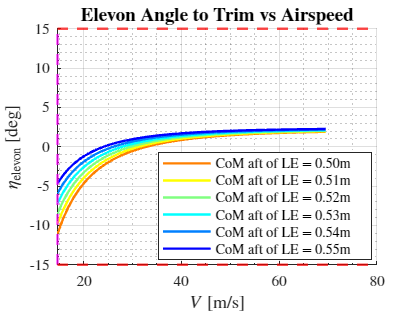


%% Figure 2 - Elevon angle
figure(2);
clf;
hold on 
grid on
grid minor
plot(velocity_ms, elevon_angle_deg, 'LineWidth', 1.5)
title('\textbf{Elevon Angle to Trim vs Airspeed}', 'FontSize', 12)
xlabel('$V$ [m/s]', 'FontSize', 11)
ylabel('$\eta_{\mathrm{elevon}}$ [deg]', 'FontSize', 11)
xline(stall_speed_ms, 'm--', 'LineWidth', 1.5, 'DisplayName', 'Stall Speed')
yline(15, 'r--', 'LineWidth',1.5, 'DisplayName', 'Upper Limit')
yline(-15, 'r--', 'LineWidth',1.5, 'DisplayName', 'Lower Limit')
set(gca,'XMinorTick','on')
set(gca,'YMinorTick','on')
legend(legend_names, 'Location', 'best')
set(gca(), 'ColorOrder', cmap)
hold off

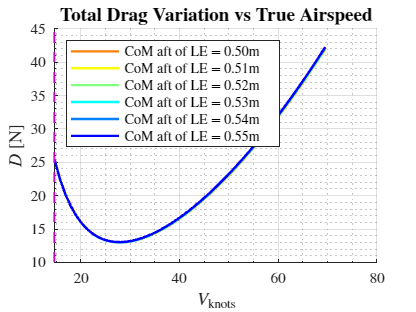


%% Figure 3 - Drag force
figure(3);
clf;
hold on 
grid on
grid minor
plot(velocity_ms, drag_force, 'LineWidth', 1.5)
title('\textbf{Total Drag Variation vs True Airspeed}', 'FontSize', 12)
xlabel('$V_{\mathrm{knots}}$', 'FontSize', 11)
ylabel('$D$ [N]', 'FontSize', 11)
xline(stall_speed_ms, 'm--', 'LineWidth',1.5, 'DisplayName', 'Stall Speed')
set(gca,'XMinorTick','on')
set(gca,'YMinorTick','on')
legend(legend_names, 'Location', 'northwest')
set(gca(), 'ColorOrder', cmap)
hold off

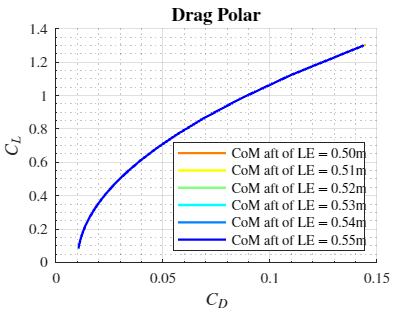


%% Figure 4 - Drag polar
figure(4);
clf;
hold on 
grid on
grid minor
plot(CD_sol, CL_sol, 'LineWidth', 1.5)
title('\textbf{Drag Polar}', 'FontSize', 12)
xlabel('$C_{D}$', 'FontSize', 11)
ylabel('$C_{L}$', 'FontSize', 11)
set(gca,'XMinorTick','on')
set(gca,'YMinorTick','on')
legend(legend_names, 'Location', 'southeast')
set(gca(), 'ColorOrder', cmap)
hold off

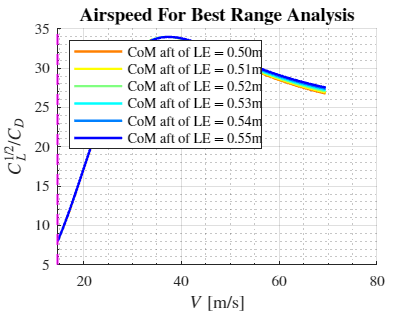


%% Figure 5 - Endurance factor
figure(5);
clf;
hold on 
grid on
grid minor
plot(velocity_ms, range, 'LineWidth', 1.5)
title('\textbf{Airspeed For Best Range Analysis}', 'FontSize', 12)
xlabel('$V$ [m/s]', 'FontSize', 11)
ylabel('${C_L^{1/2}}/{C_D}$', 'FontSize', 11)
xline(stall_speed_ms, 'm--', 'LineWidth', 1.5, 'DisplayName', 'Stall Speed')
set(gca,'XMinorTick','on')
set(gca,'YMinorTick','on')
legend(legend_names, 'Location', 'northwest')
set(gca(), 'ColorOrder', cmap)
hold off